## P1 程序设计基础

## 1.0 Matlab软件界面和M文件

软件界面包含：

- 功能区（Ribbon）：位于顶部，含“主页”（文件/变量/代码操作）、“绘图”（可视化命令）、"APP"（应用工具如`plot(x,y)` 将 `x` 作为横坐标、`y` 作为纵坐标，并按照数据顺序连接各个采样点。 App DesignerSimulink）三大选项卡

- 命令行窗口（Command Window）：核心交互区，用于输入指令、执行脚本、查看即时输出及调用帮助（如 `help` 命令）

- 工作区Workspace）‌：显示当前内存中所有变量的名称、值、类型、大小，支持双击编辑、重命名、绘图及清除操作 

- 当前文件夹（Current Folder）‌：展示默认工作目录下的文件，决定脚本执行路径与资源加载范围，可快速切换或导入数据。注意需要执行的文件，须将其所在文件夹添加至路径

文件类型

-  **.m 文件：脚本、函数、类

-  **.slx 文件：Simulink模型

-  **.mlx 文件：实时脚本

## 1.1 MATLAB程序设计语言基础

### 1.1.1 变量与常量

**有效名称**

- 有效的变量名称以英文字母开头，后跟字母、数字或下划线。区分大小写，因此 `A` 和 `a` *不是*同一变量。变量名称的最大长度为 `namelengthmax` 命令返回的值。

a = 1 % 有效变量

a = 1

% _a = 2 % 无效变量

- 不能定义与 MATLAB 关键字同名的变量（例如 `if` 或 `end`）。关键字的完整列表，请运行 `iskeyword` 命令。

- 定义变量时应避免创建与函数同名的变量，例如 `i`、`j`、`mode`、`char`、`size` 和 `path`。一般情况下，变量名称优先于函数名称。

keyList = iskeyword

keyList = 20×1 cell 数组
    {'break'     }
    {'case'      }
    {'catch'     }
    {'classdef'  }
    {'continue'  }
    {'else'      }
    {'elseif'    }
    {'end'       }
    {'for'       }
    {'function'  }
    {'global'    }
    {'if'        }
    {'otherwise' }
    {'parfor'    }
    {'persistent'}
    {'return'    }
    {'spmd'      }
    {'switch'    }
    {'try'       }
    {'while'     }


**系统预定义变量和常量**

- `ans`：最近一次未赋值运算的结果存储变量

- `pi`：圆周率 π（约 3.14159...）

- `i` 或 `j`：虚数单位，表示 \(\sqrt{-1}\)

- `Inf` 或 `inf`：无穷大（Infinity），例如由 `1/0` 产生

- `NaN`：表示“不是一个数字”（Not-a-Number），例如由 `0/0` 产生

- `eps`：计算机的浮点相对精度（极小正数，约 1.22 × 10⁻¹⁶）

- `realmin`：正规化的最小正浮点数（约 2.22 × 10⁻³⁰⁸）

- `realmax`：最大正浮点数（约 1.79 × 10308）

- `true` / `false`：逻辑真与逻辑假

pi

ans = 3.1416

1i

ans = 0.0000 + 1.0000i

inf

ans = Inf

NaN

ans = NaN

eps

ans = 2.2204e-16

realmin

ans = 2.2251e-308

realmax

ans = 1.7977e+308

true

ans = logical
   1


false

ans = logical
   0


### 1.1.2 数据结构

变量的数据结构可以通过工作区查询，也可使用class()命令读取

class(a)

ans = 'double'

#### 数值类型（整数和浮点数据）

- 数值类包括有符号和无符号整数、单精度和双精度浮点数。默认情况下，MATLAB 以双精度浮点形式存储所有数值。

- 与双精度数组相比，以整数和单精度数组形式存储数据更节省内存。

- 所有数值类型都支持基本的数组运算，例如添加索引、重构和数学运算

- 和C语言类似，通过以下命令创建数值变量

- 8位为一个字节

b = double([1/2 4.1 pi]); disp(b)

    0.5000    4.1000    3.1416



c = int16([7 8 9])

c = 1×3 int16 行向量
   7   8   9


默认情况下数值变量均为double类型

A = [1 2 3; 4 5 6];
A = A + 1;
disp(A)

     2     3     4
     5     6     7



#### 符号型数据

“符号对象”这种特殊的数据类型包括符号数、符号变量、符号表达式和符号函数。它还包括符号数、变量、表达式和函数的向量、矩阵和多维数组。

符号变量、向量、矩阵和数组

% 创建符号变量 x 和 y。
x = sym("x")

$$x = x$$

y = sym("y")

$$y = y$$

z = diff(cos(x)); % 求导运算
disp(z)

$$-\sin\left(x\right)$$

pretty(z) % 用latex风格显示符号公式

-sin(x)



% 创建一个 1×4 符号向量 a
a = sym("a",[1 4])

$$a = \left(\begin{array}{cccc} a_{1} & a_{2} & a_{3} & a_{4} \end{array}\right)$$

% 获取第2个元素
a(2)

$$ans = a_{2}$$

% 创建一个 3×4 符号矩阵，其中包含自动生成的元素
A = sym("A",[3 4])

$$A = \left(\begin{array}{cccc} A_{1,1} & A_{1,2} & A_{1,3} & A_{1,4}\\ A_{2,1} & A_{2,2} & A_{2,3} & A_{2,4}\\ A_{3,1} & A_{3,2} & A_{3,3} & A_{3,4} \end{array}\right)$$

A(2,3)

$$ans = A_{2,3}$$

符号数或表达式

a = sym(1/3)

$$a = \frac{1}{3}$$

b = 1/3

b = 0.3333

a*3

$$ans = 1$$

b*3

ans = 1

% 为了获得更高的精度，请对子表达式而不是对整个表达式使用 sym。
% 对整个表达式使用 sym 会导致结果不精确，因为 MATLAB首先会将表达式转换为浮点数，这会导致精度损失。
inaccurate1 = sym(1/1234567)

$$inaccurate1 = \frac{7650239286923505}{9444732965739290427392}$$

accurate1 = 1/sym(1234567)

$$accurate1 = \frac{1}{1234567}$$

符号函数

% 创建具有一个和两个参量的符号函数
syms s(t) f(x,y)
s(t) = [t t^3; 1-t cos(t*pi/6)]

$$s(t) = \left(\begin{array}{cc} t & t^{3}\\ 1-t & \cos\left(\frac{\pi \,t}{6}\right) \end{array}\right)$$

f(x,y) = x + 2*y

$$f(x, y) = x+2\,y$$

% 计算 t = 2 时函数的值
s(2)

$$ans = \left(\begin{array}{cc} 2 & 8\\ -1 & \frac{1}{2} \end{array}\right)$$

% 计算 s 的导数
diff(s)

$$ans(t) = \left(\begin{array}{cc} 1 & 3\,t^{2}\\ -1 & -\frac{\pi \,\sin\left(\frac{\pi \,t}{6}\right)}{6} \end{array}\right)$$

% 计算 f 的梯度
gradient(f)

$$ans(x, y) = \left(\begin{array}{c} 1\\ 2 \end{array}\right)$$

### 1.1.3 基本语句结构

MATLAB 语句通常由赋值、函数调用和控制符号组成。分号用于抑制命令行显示，百分号后的内容为注释；较长表达式可用省略号续行。

% 赋值、分号、注释和续行的基本用法
P1_scalar = 3;                 %基本赋值语句
P1_v1 = [1 2 3 4]

P1_v1 =      1     2     3     4


P1_v2 = [1, 2, 3, ...
    4]                        % 省略号表示语句在下一行继续

P1_v2 =      1     2     3     4


P1_m1 = [1 2; 3 4]             % 方括号内的分号表示矩阵换行

P1_m1 =      1     2
     3     4


P1_m2 = [1 2
    3 4]

P1_m2 =      1     2
     3     4


还可以通过分号观察输出抑制效果：

% 末尾有分号，不会自动显示
P1_suppressedValue = 10;

% 末尾没有分号，会自动显示
P1_displayValue = 20

P1_displayValue = 20

### 1.1.4 冒号表达式与子矩阵提取

冒号表达式可产生等间隔序列。$\({v}=s_1:s_2:s_3\)$，该函数将生成一个行向量$\({v}\)$，其中$\(s_1\)$为向量的起始值，$$s_2$$为步距，该向量将从$\(s_1\)$出发，每隔步距$$s_2$$取一个点，直至不超过$$s_3$$的最大值就可以构成一个向量。若省略$$s_2$$，则步距取默认值1。下面通过例子演示冒号表达式的应用。

% 用冒号表达式生成递增和递减序列
P1_x1 = 0:0.5:2.1; %注意，最终取值为2而不是2.1
P1_x2 = 0:2.1; %取默认步距1
P1_x3 = 2:-0.5:0;

disp(P1_x1)

         0    0.5000    1.0000    1.5000    2.0000



disp(P1_x2)

     0     1     2



disp(P1_x3)

    2.0000    1.5000    1.0000    0.5000         0



也可在矩阵索引中选取连续行、列或全部元素。end 表示当前维度的最后一个下标。提取子矩阵的具体方式是$B=A(v_1,v_2)$

% 构造矩阵并提取子矩阵、指定行和最后一列
P1_indexMatrix = reshape(1:12,3,4) %把1:12重排成一个3×4矩阵 , MATLAB 按列填充

P1_indexMatrix =      1     4     7    10
     2     5     8    11
     3     6     9    12


P1_subMatrix = P1_indexMatrix(1:2,2:4) %提取第1-2行，第2-4列 

P1_subMatrix =      4     7    10
     5     8    11


P1_selectedRows = P1_indexMatrix([1,3],:) %提取1，3行，所有列

P1_selectedRows =      1     4     7    10
     3     6     9    12


## 1.2 基本数学运算

### 1.2.1 矩阵的代数运算

本节区分矩阵运算和逐元素运算，并介绍逻辑、比较、符号化简与基本数论函数。使用矩阵运算符时，要先确认参与运算矩阵的维数是否匹配。

加减法、乘法、幂和转置属于常用矩阵代数运算；带点的运算符（如 .* 和 .^）表示逐元素运算。

% 定义两个同阶矩阵，比较矩阵运算与逐元素运算
P1_A = [2, 1; 1, 3];
P1_B = [1, 4; 2, 0];
P1_sumAB = P1_A + P1_B;
P1_productAB = P1_A * P1_B;
P1_elementProduct = P1_A .* P1_B;
P1_matrixPower = P1_A^2;
P1_elementPower = P1_A.^2;

disp('矩阵A：')

矩阵A：


disp(P1_A)

     2     1
     1     3



disp('矩阵B：')

矩阵B：


disp(P1_B)

     1     4
     2     0



disp('加运算：')

加运算：


disp(P1_sumAB)

     3     5
     3     3



disp('乘积运算：')

乘积运算：


disp(P1_productAB)

     4     8
     7     4



disp('点乘运算：')

点乘运算：


disp(P1_elementProduct)

     2     4
     2     0



disp('乘方运算：')

乘方运算：


disp(P1_matrixPower)

     5     5
     5    10



disp('点乘方运算：')

点乘方运算：


disp(P1_elementPower)

     4     1
     1     9



线性方程 Ax=b 通常用**左除** A\b 求解。

% 使用左除求解线性方程 Ax=b
P1_b = [1;2];
P1_x = P1_A\P1_b;

% 计算方程残差（向量的模）
P1_residual = norm(P1_A*P1_x-P1_b);

% 判断残差是否足够小
P1_solutionIsAccurate = P1_residual < 1e-12;

disp('线性方程的解：')

线性方程的解：


disp(P1_x)

    0.2000
    0.6000




disp('线性方程残差：')

线性方程残差：


disp(P1_residual)

   2.2204e-16




disp('解是否满足精度要求：')

解是否满足精度要求：


disp(P1_solutionIsAccurate)

   1



### 1.2.2 逻辑运算

逻辑运算会把非零元素视为真、零元素视为假。&、| 和 ~ 分别表示逐元素的“与”“或”和“非”。

% 构造两个矩阵并进行逐元素逻辑运算
P1_M = [1, 0, 3; 4, 5, 0];
P1_N = [0, 2, 3; 4, 0, 6];
P1_logicAnd = P1_M & P1_N;
P1_logicOr = P1_M | P1_N;
P1_logicNot = ~P1_M;

disp(P1_M)

     1     0     3
     4     5     0



disp(P1_N)

     0     2     3
     4     0     6



disp(P1_logicAnd)

   0   0   1
   1   0   0



disp(P1_logicOr)

   1   1   1
   1   1   1



disp(P1_logicNot)

   0   1   0
   0   0   1



### 1.2.3 比较运算

比较运算符会返回逻辑矩阵。find 用于获得满足条件元素的下标，all 和 any 分别用于判断是否全部或至少一个元素满足条件。

% 比较矩阵元素并定位满足条件的位置
P1_geTwo = P1_M >= 2;
[P1_row, P1_col] = find(P1_M > 2);
P1_allNonnegative = all(P1_M >= 0); %默认下，比较每一列的向量是否全部满足条件，即某列元素均大于等于0，相应元素为1
P1_hasZero = any(P1_M == 0); %默认下，比较每一列的向量是否至少一个满足条件，即某列元素存在等于0的元素，相应元素为1

disp(P1_M)

     1     0     3
     4     5     0



disp(P1_geTwo)

   0   0   1
   1   1   0



disp([P1_row, P1_col])

     2     1
     2     2
     1     3



disp(P1_allNonnegative)

   1   1   1



disp(P1_hasZero)

   0   1   1



### 1.2.4 符号运算

对于符号表达式，可用 simplify 化简、expand 展开、factor 因式分解，并使用 subs 完成变量替换。

clear s z
% 定义符号变量
syms s z

% 定义符号多项式
P1_poly = (s+3)^2 * ...
    (s^2+3*s+2) * ...
    (s^3+12*s^2+48*s+64);

% 化简、展开和因式分解
P1_simplified = simplify(P1_poly);
P1_expanded = expand(P1_poly);
P1_factored = factor(P1_expanded);

% 将 s 替换为 (z+1)/(z-1)
P1_substituted = simplify( ...
    subs(P1_poly,s,(z+1)/(z-1)));

disp('原始表达式：')

原始表达式：


disp(P1_poly)

$${\left(s+3\right)}^{2}\,\left(s^{2}+3\,s+2\right)\,\left(s^{3}+12\,s^{2}+48\,s+64\right)$$

disp('化简结果：')

化简结果：


disp(P1_simplified)

$${\left(s+3\right)}^{2}\,{\left(s+4\right)}^{3}\,\left(s^{2}+3\,s+2\right)$$

disp('展开结果：')

展开结果：


disp(P1_expanded)

$$s^{7}+21\,s^{6}+185\,s^{5}+883\,s^{4}+2454\,s^{3}+3944\,s^{2}+3360\,s+1152$$

disp('因式分解结果：')

因式分解结果：


disp(P1_factored)

$$\left(\begin{array}{ccccccc} s+2 & s+1 & s+3 & s+3 & s+4 & s+4 & s+4 \end{array}\right)$$

disp('变量替换结果：')

变量替换结果：


disp(P1_substituted)

$$\frac{8\,z\,{\left(2\,z-1\right)}^{2}\,\left(3\,z-1\right)\,{\left(5\,z-3\right)}^{3}}{{\left(z-1\right)}^{7}}$$

## 1.3 流程结构

MATLAB 程序通常按照从上到下的顺序执行。流程结构用于改变这种顺序，主要包括循环结构、条件转移结构、开关结构和试探结构。

### 1.3.1 循环结构

for 循环适合已知循环次数的计算；while 循环在条件为真时持续执行，适合循环次数不确定、但有明确终止条件的情况。

% 使用 for 循环计算 1 到 100 的累加和
P1_sumFor = 0;

for P1_k = 1:100
    P1_sumFor = P1_sumFor + P1_k;
end

% 使用 MATLAB 内置函数验证结果
P1_sumExpected = sum(1:100);

% 使用 while 循环寻找累加和第一次超过 10000 的整数
P1_m = 0;
P1_sumWhile = 0;

while P1_sumWhile <= 10000
    P1_m = P1_m + 1;
    P1_sumWhile = P1_sumWhile + P1_m;
end

fprintf('for 循环累加和 = %d\n',P1_sumFor)

for 循环累加和 = 5050


fprintf('理论累加和     = %d\n',P1_sumExpected)

理论累加和     = 5050


fprintf('while 循环终止整数 = %d\n',P1_m)

while 循环终止整数 = 141


fprintf('while 循环最终累加和 = %d\n',P1_sumWhile)

while 循环最终累加和 = 10011


### 1.3.2 条件转移结构

if、elseif 和 else 根据逻辑条件选择不同分支。程序首先判断 `if` 条件，如果不满足，再判断 `elseif`，最后执行 `else`。条件表达式的结果应为逻辑标量或可转换为逻辑标量的值。

% 判断 for 循环计算结果是否正确
if P1_sumFor == P1_sumExpected
    P1_conditionResult = "for 循环结果正确";
elseif P1_sumFor > P1_sumExpected
    P1_conditionResult = "累加结果偏大";
else
    P1_conditionResult = "累加结果偏小";
end

disp('条件判断结果：')

条件判断结果：


disp(P1_conditionResult)

for 循环结果正确


### 1.3.3 开关结构

switch 根据一个表达式的不同取值选择 case 分支；otherwise 负责处理未被列出的其他情况。

% 用状态码表示系统当前状态
P1_stateCode = 2;

switch P1_stateCode
    case 1
        P1_stateText = "idle";
    case {2,3}
        % case {2,3} 表示状态码为 2 或 3 时执行同一分支
        P1_stateText = "running";
    otherwise
        P1_stateText = "unknown";
end

fprintf('状态码 = %d\n',P1_stateCode)

状态码 = 2


disp('系统状态：')

系统状态：


disp(P1_stateText)

running


### 1.3.4 试探结构

`try/catch` 用于处理程序运行过程中可能出现的错误。`try` 中的代码正常执行时，跳过 `catch`；如果发生错误，则转到 `catch` 分支。

% 构造一个奇异矩阵
try
    P1_singular = zeros(2);

    % rcond 为 0，说明矩阵是奇异矩阵
    if rcond(P1_singular) == 0
        error('P1:SingularMatrix', ...
            '矩阵为奇异矩阵，不能直接求逆。')
    end

catch P1_ME
    % 读取异常对象中的错误信息
    P1_errorMessage = P1_ME.message;
    P1_errorIdentifier = P1_ME.identifier;
end

disp('错误标识符：')

错误标识符：


disp(P1_errorIdentifier)

P1:SingularMatrix



disp('错误信息：')

错误信息：


disp(P1_errorMessage)

矩阵为奇异矩阵，不能直接求逆。


## 1.4 函数编写与调试

函数可以将重复使用的计算过程封装起来。一个函数通常包含输入参数、输出参数和函数主体。调试函数时，应检查输入是否正确、输出是否符合预期，以及计算残差是否足够小。

### 1.4.1 MATLAB语言函数的基本结构

函数定义以 function 开头，方括号中给出输出变量，圆括号中给出输入变量。下面调用文末定义的局部函数计算累加和。

% 局部函数P1_findsum放在实时脚本的末尾，避免与脚本主体混排。
% 调用局部函数，计算 1 到 100 的累加和
[P1_sum100,P1_sequence100] = P1_findsum(100);

% 检查函数返回的累加结果和最后一个序列元素
fprintf('函数计算的累加和 = %d\n',P1_sum100)

函数计算的累加和 = 5050


fprintf('序列最后一个元素 = %d\n',P1_sequence100(end))

序列最后一个元素 = 100


### 1.4.2 可变输入输出个数的处理

`varargin` 用于接收数量不固定的输入参数。它会把所有输入参数保存到一个单元数组中。

`varargout` 用于返回数量不固定的输出参数。下面的函数可以接收多个向量，并返回均值；如果调用时要求两个输出，还会返回标准差。。

% 只接收一个输出时，函数返回均值
P1_meanOnly = P1_summary(1:5,6:10);

% 接收两个输出时，函数返回均值和标准差
[P1_meanValue,P1_stdValue] = P1_summary(1:5,6:10);

fprintf('只返回均值：%.4f\n',P1_meanOnly)

只返回均值：5.5000


fprintf('均值：%.4f\n',P1_meanValue)

均值：5.5000


fprintf('标准差：%.4f\n',P1_stdValue)

标准差：3.0277


### 1.4.3 匿名函数与 inline 函数

匿名函数以 @ 创建，适合表达式较短的函数

% 创建匿名函数
P1_fun = @(x,y) sin(x.^2+y.^2) + x.*y;

% 计算匿名函数在指定点处的值
P1_anonymousValue = P1_fun(pi/4,1/2);

% 新版本 MATLAB 使用inline会报警告——以后的版本中会删除LNLINE，请改用匿名函数
P1_inlineValue = P1_anonymousValue;

fprintf('匿名函数结果 = %.6f\n',P1_anonymousValue)

匿名函数结果 = 1.154993


## 1.5 二维图形绘制

二维图形通常由横坐标数据和纵坐标数据组成。MATLAB 中最常用的二维绘图函数是 `plot`。绘图后还可以使用 `grid`、`xlabel`、`ylabel`、`title` 和 `legend` 对图形进行说明。。

### 1.5.1 二维图形绘制基本语句

plot 是最常用的二维曲线绘制函数。`plot(x,y)` 将 `x` 作为横坐标、`y` 作为纵坐标，并按照数据顺序连接各个采样点。教材中的不规则采样曲线可用于观察采样间隔和函数变化对图形效果的影响。

% 1.5.1 不同步长下的二维曲线绘制
% 使用较小步长，采样点较密
P1_xFine = -pi:0.05:pi;
P1_yFine = sin(tan(P1_xFine)) - tan(sin(P1_xFine));

% 使用较大步长，采样点较稀
P1_xCoarse = -pi:0.2:pi;
P1_yCoarse = sin(tan(P1_xCoarse)) - tan(sin(P1_xCoarse));

% 显示两种步长对应的采样点数量
fprintf('细步长采样点数量：%d\n',numel(P1_xFine))

细步长采样点数量：126


fprintf('粗步长采样点数量：%d\n',numel(P1_xCoarse))

粗步长采样点数量：32


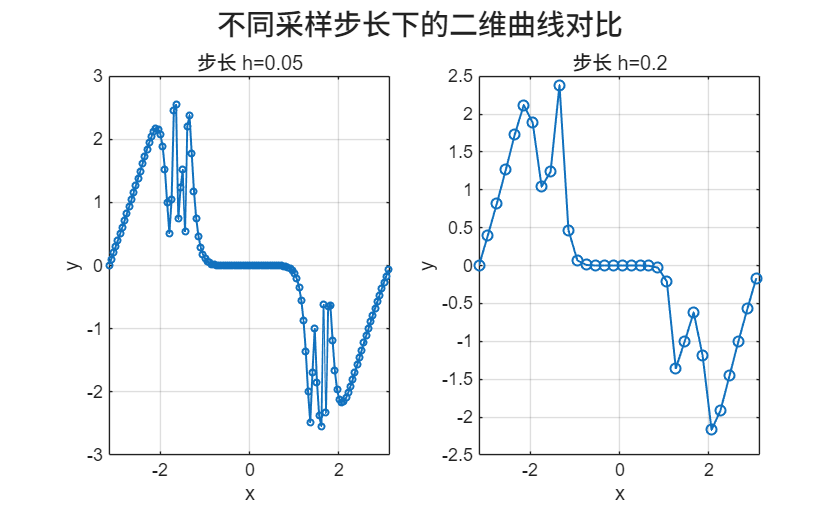


% 创建图形窗口
figure('Color','w')

% 绘制细步长曲线
subplot(1,2,1)
plot(P1_xFine,P1_yFine,'o-','MarkerSize',3, ...
    'LineWidth',1.0)
grid on
xlabel('x')
ylabel('y')
title('步长 h=0.05')
xlim([-pi,pi])

% 绘制粗步长曲线
subplot(1,2,2)
plot(P1_xCoarse,P1_yCoarse,'o-','MarkerSize',5, ...
    'LineWidth',1.0)
grid on
xlabel('x')
ylabel('y')
title('步长 h=0.2')
xlim([-pi,pi])

% 设置总标题
sgtitle('不同采样步长下的二维曲线对比')

实际上是等间隔采样，采样本身却并不不规则。真正导致曲线看起来不规则的是：

- `tan(x)` 在$\(x=\pm\frac{\pi}{2}\) $附近变化非常快；

- `sin(tan(x))` 会产生快速振荡；

- 如果采样步长较大，可能漏掉部分振荡；

- `plot` 会用直线连接相邻采样点，使图形看起来更加不规则。

### 1.5.2 其他二维图形绘制语句

除了 `plot`，MATLAB 还提供了多种专用绘图函数：

- `polarplot`：绘制极坐标曲线；

- `stairs`：绘制阶梯曲线；

- `stem`：绘制离散数据；

- `semilogx`：横坐标采用对数坐标。

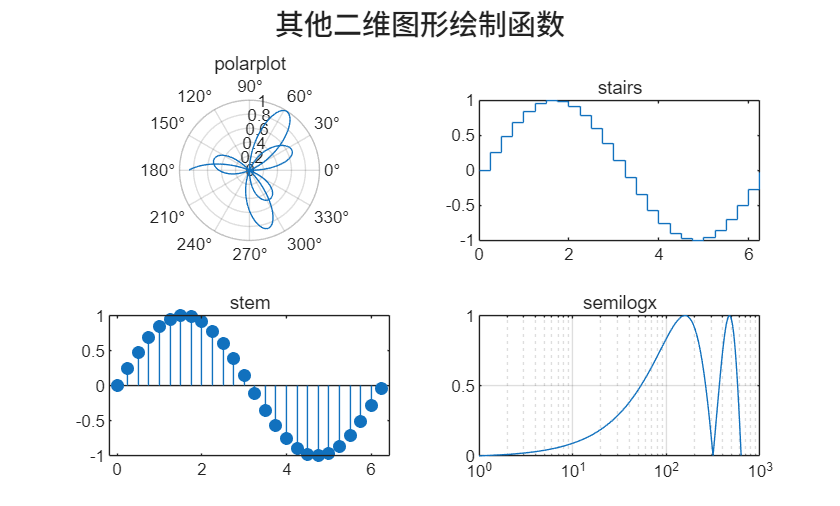

% 生成角度数据
P1_tPlot = 0:0.01:2*pi;

% 定义极坐标曲线的半径
P1_rPlot = sin(8*P1_tPlot/3) ./ ...
    (2-cos(3*P1_tPlot/2).^2);

% 创建图形窗口
figure('Color','w')

% 将窗口划分为 2×2 个子图
subplot(2,2,1)

% 绘制极坐标曲线
polarplot(P1_tPlot,P1_rPlot)
title('polarplot')

% 绘制阶梯图
subplot(2,2,2)
P1_sampleIndex = 1:25:numel(P1_tPlot);
stairs(P1_tPlot(P1_sampleIndex), ...
    sin(P1_tPlot(P1_sampleIndex)))
title('stairs')

% 绘制离散数据图
subplot(2,2,3)
stem(P1_tPlot(P1_sampleIndex), ...
    sin(P1_tPlot(P1_sampleIndex)),'filled')
title('stem')

% 绘制横坐标为对数坐标的曲线
subplot(2,2,4)
semilogx(1:numel(P1_tPlot), ...
    abs(sin(P1_tPlot))+eps)
grid on
title('semilogx')

% 添加总标题
sgtitle('其他二维图形绘制函数')

### 1.5.3 图形修饰

图形修饰包括线型、网格、坐标范围、参考线、图例、坐标轴标签和标题。

例如：

- `xline`：添加竖直参考线；

- `yline`：添加水平参考线；

- `legend`：添加图例；

- `xlim`、`ylim`：设置坐标范围；

- `hold on`：在当前图形上继续绘图。

这些设置不会改变数据，但会显著改善图形的可读性。

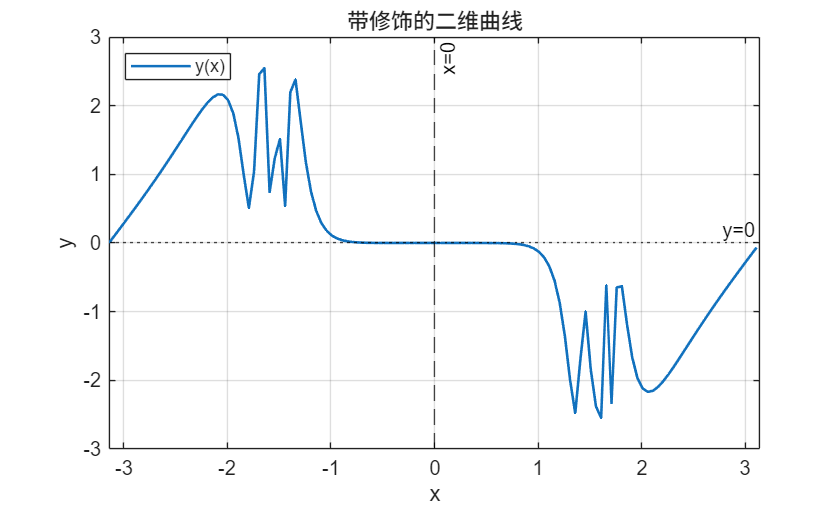

% 创建图形窗口
figure('Color','w')

% 绘制二维曲线
plot(P1_xFine,P1_yFine,'LineWidth',1.3)

% 保留当前曲线，允许继续添加参考线
hold on

% 添加 x=0 和 y=0 参考线
xline(0,'k--','x=0')
yline(0,'k:','y=0')

% 显示网格
grid on

% 添加图例
legend('y(x)','Location','northwest')

% 设置坐标轴标签
xlabel('x')
ylabel('y')

% 设置标题和横坐标范围
title('带修饰的二维曲线')
xlim([-pi,pi])

% 关闭叠加绘图模式
hold off

## 1.6 三维图形表示

三维曲线和曲面用于描述多个变量之间的关系。曲面绘制通常先用 meshgrid 建立网格，再计算每个网格点上的函数值。

### 1.6.1 三维曲线绘制

plot3 用于连续三维曲线，stem3 用于三维离散样本。两者都需要分别给出 x、y、z 三个坐标分量。

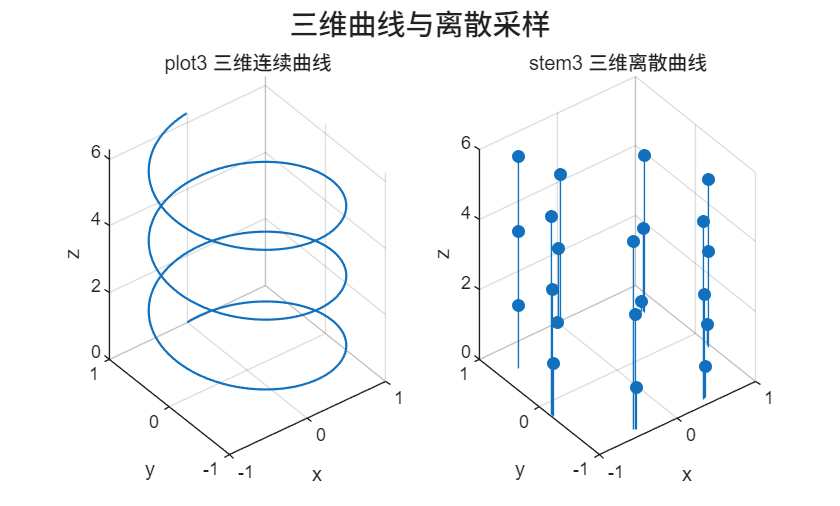

% 生成参数变量
P1_t3 = 0:0.01:2*pi;

% 定义三维曲线的三个坐标
P1_x3 = sin(3*P1_t3);
P1_y3 = cos(3*P1_t3);
P1_z3 = P1_t3;

% 创建图形窗口
figure('Color','w')

% 绘制连续三维曲线
subplot(1,2,1)
plot3(P1_x3,P1_y3,P1_z3,'LineWidth',1.1)
grid on
xlabel('x')
ylabel('y')
zlabel('z')
title('plot3 三维连续曲线')

% 每隔 30 个点取一个样本，绘制三维离散图
subplot(1,2,2)
P1_sample3 = 1:30:numel(P1_t3);
stem3(P1_x3(P1_sample3), ...
      P1_y3(P1_sample3), ...
      P1_z3(P1_sample3),'filled')
grid on
xlabel('x')
ylabel('y')
zlabel('z')
title('stem3 三维离散曲线')

% 添加总标题
sgtitle('三维曲线与离散采样')

### 1.6.2 三维曲面绘制*

三维曲面绘制通常分三步：

- 第一步，使用 `meshgrid` 生成网格；

- 第二步，计算每个网格点上的函数值；

- 第三步，使用 `mesh`、`surf` 或 `contour3` 绘图。

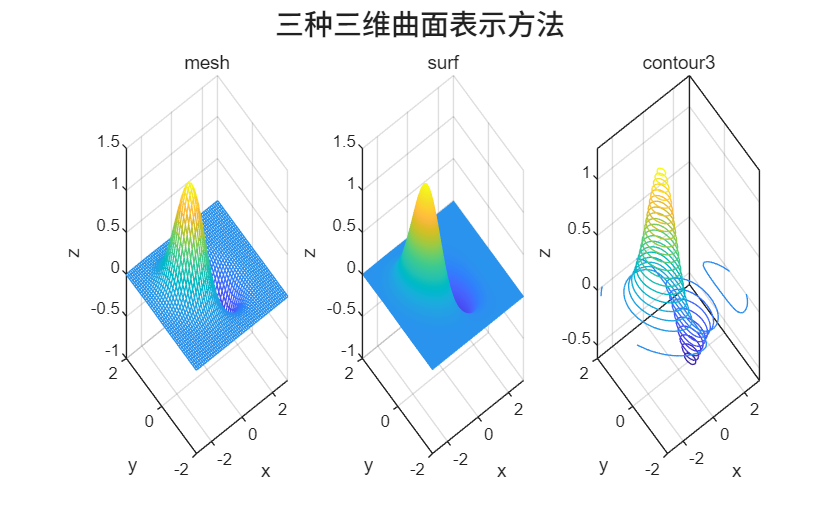

% 生成二维网格
[P1_XGrid,P1_YGrid] = ...
    meshgrid(-3:0.1:3,-2:0.1:2);

% 根据网格坐标计算曲面高度
P1_ZGrid = (P1_XGrid.^2-2*P1_XGrid) .* ...
    exp(-P1_XGrid.^2 ...
    -2*P1_YGrid.^2 ...
    -P1_XGrid.*P1_YGrid);

% 创建图形窗口
figure('Color','w')

% 使用网格形式绘制曲面
subplot(1,3,1)
mesh(P1_XGrid,P1_YGrid,P1_ZGrid)
xlabel('x')
ylabel('y')
zlabel('z')
title('mesh')
grid on

% 使用着色曲面形式绘制
subplot(1,3,2)
surf(P1_XGrid,P1_YGrid,P1_ZGrid)
shading interp
xlabel('x')
ylabel('y')
zlabel('z')
title('surf')
grid on

% 使用三维等高线形式绘制
subplot(1,3,3)
contour3(P1_XGrid,P1_YGrid,P1_ZGrid,30)
xlabel('x')
ylabel('y')
zlabel('z')
title('contour3')
grid on

% 设置总标题
sgtitle('三种三维曲面表示方法')

`meshgrid` 生成的 P1_`XGrid` 和 P1_`YGrid` 是同样大小的矩阵。P1_`ZGrid` 中的每个元素表示对应网格点处的高度。

三种绘图效果分别为：

- `mesh`：显示曲面的网格结构；

- `surf`：显示具有颜色的三维曲面；

- `contour3`：显示三维等高线。

### 1.6.3 三维图形视角设置*

`view(azimuth,elevation)` 用于设置观察角度：

其中：

- `azimuth` 表示方位角；

- `elevation` 表示仰角；

- `view(0,90)` 表示俯视图；

- `view(0,0)` 表示正视图；

- `view(90,0)` 表示右视图；

- `view(3)` 表示默认立体视图。

视角设置只对当前坐标区有效，因此必须在 `surf` 绘图命令之后调用 `view`。

#### 改变分段曲面的观察视角

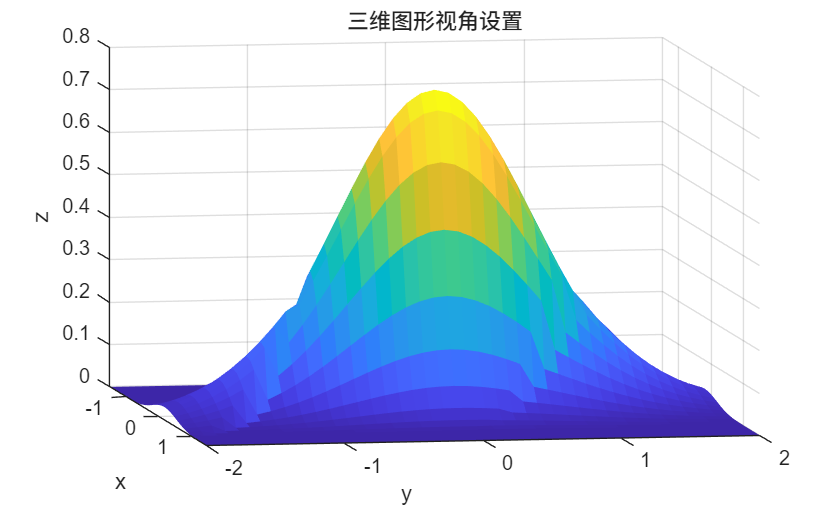

% 生成网格
[P1_x1,P1_x2] = meshgrid(-1.5:.1:1.5,-2:.1:2);

% 构造分段三维曲面
P1_z = 0.5457*exp(-0.75*P1_x2.^2-3.75*P1_x1.^2-1.5*P1_x1).*(P1_x1+P1_x2>1) + 0.7575*exp(-P1_x2.^2-6*P1_x1.^2).*((P1_x1+P1_x2>-1)&(P1_x1+P1_x2<=1)) + 0.5457*exp(-0.75*P1_x2.^2-3.75*P1_x1.^2+1.5*P1_x1).*(P1_x1+P1_x2<=-1);

% 绘制三维曲面
figure('Color','w')
surf(P1_x1,P1_x2,P1_z)

% 设置观察视角和显示范围
view(80,10)
xlim([-1.5 1.5])

% 设置曲面显示方式
shading flat

grid on
xlabel('x')
ylabel('y')
zlabel('z')
title('三维图形视角设置')

#### 同一曲面在不同视角下的显示

使用曲面：$\[ z=(x^2-2x)\exp(-x^2-2y^2-xy) \]$

对应 MATLAB 代码如下：

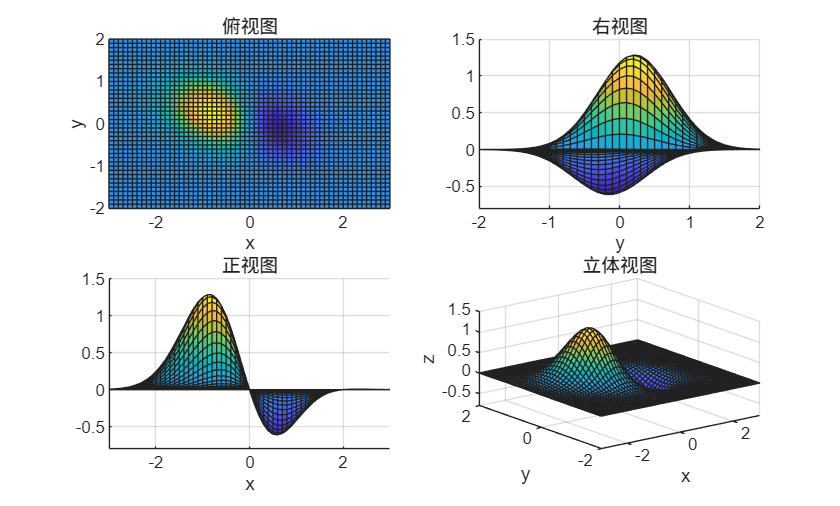

% 生成网格
[P1_x1,P1_x2] = meshgrid(-3:0.1:3,-2:0.1:2);

% 定义曲面
P1_z = (P1_x1.^2-2*P1_x1).*exp(-P1_x1.^2-2*P1_x2.^2-P1_x1.*P1_x2);

% 设置坐标范围
P1_axisRange = [-3 3 -2 2 -0.8 1.5];

% 创建图形窗口
figure('Color','w')

% 俯视图
subplot(2,2,1)
surf(P1_x1,P1_x2,P1_z)
view(0,90)
axis(P1_axisRange)
grid on
xlabel('x')
ylabel('y')
title('俯视图')

% 右视图
subplot(2,2,2)
surf(P1_x1,P1_x2,P1_z)
view(90,0)
axis(P1_axisRange)
grid on
xlabel('x')
ylabel('y')
title('右视图')

% 正视图
subplot(2,2,3)
surf(P1_x1,P1_x2,P1_z)
view(0,0)
axis(P1_axisRange)
grid on
xlabel('x')
ylabel('y')
title('正视图')

% 立体视图
subplot(2,2,4)
surf(P1_x1,P1_x2,P1_z)
view(3)
axis(P1_axisRange)
grid on
xlabel('x')
ylabel('y')
zlabel('z')
title('立体视图')

不同视角的作用是：

- 俯视图便于观察曲面的平面分布；

- 正视图便于观察曲面沿一个方向的高度变化；

- 右视图便于观察另一个方向的高度变化；

- 立体视图能够同时观察曲面的整体形状、峰值和谷值。

下面给出 1.4 节示例所调用的局部函数。

function [sumValue,sequence] = P1_findsum(limit)
%P1_FINDSUM 计算从 1 到 limit 的整数和。
if nargin < 1
    limit = 100;
end
sequence = 1:limit;
sumValue = sum(sequence);
end

function [meanValue,varargout] = P1_summary(varargin)
%P1_SUMMARY 汇总任意数量输入向量的均值和标准差。
data = [varargin{:}];
meanValue = mean(data);
if nargout > 1
    varargout{1} = std(data);
end
end

